% y*dx-(x+y^2)*dy=0 (mu=phi(y))

% 1)
clear
% y'=y/(x+y^2)
syms x y(x)
eqn=diff(y(x))==y/(x+y^2)

$$eqn(x) = \frac{\partial }{\partial x}y\left(x\right)=\frac{y\left(x\right)}{{y\left(x\right)}^{2}+x}$$

ySol=dsolve(eqn)

$$ySol = \left(\begin{array}{c} 0\\ \sqrt{x}\\ -\sqrt{x}\\ \sqrt{x}\,\left(\frac{{\mathrm{e}}^{C_{7}-\frac{\log\left(x\right)}{2}}}{2}+\frac{\sqrt{{\mathrm{e}}^{2\,C_{7}-\log\left(x\right)}+4}}{2}\right)\\ \sqrt{x}\,\left(\frac{{\mathrm{e}}^{C_{7}-\frac{\log\left(x\right)}{2}}}{2}-\frac{\sqrt{{\mathrm{e}}^{2\,C_{7}-\log\left(x\right)}+4}}{2}\right) \end{array}\right)$$

%                                                                 0
%                                                           x^(1/2)
%                                                          -x^(1/2)
% x^(1/2)*(exp(C5 - log(x)/2)/2 + (exp(2*C5 - log(x)) + 4)^(1/2)/2)
% x^(1/2)*(exp(C5 - log(x)/2)/2 - (exp(2*C5 - log(x)) + 4)^(1/2)/2)

% 2)
clear
% x'=(x+y^2)/y
syms y x(y)
eqn=diff(x(y))==(x+y^2)/y

$$eqn(y) = \frac{\partial }{\partial y}x\left(y\right)=\frac{x\left(y\right)+y^{2}}{y}$$

xSol=dsolve(eqn)

$$xSol = y^{2}+C_{9}\,y$$

% y^2 + C7*y

% 3)
syms x y dx dy
eq1=y*dx-(x+y^2)*dy

$$eq1 = \mathrm{dx}\,y-\mathrm{dy}\,\left(y^{2}+x\right)$$

cfs=coeffs(eq1,[dy dx])

$$cfs = \left(\begin{array}{cc} y & -y^{2}-x \end{array}\right)$$

P=cfs(1), Q=cfs(2)

$$P = y$$

$$Q = -y^{2}-x$$

f=simplify(diff(P,y)-diff(Q,x))

$$f = 2$$

% dPy/=dQx

eq1=f/P

$$eq1 = \frac{2}{y}$$

% 2/y
mu=exp(-int(eq1,y))

$$mu = \frac{1}{y^{2}}$$

% 1/y^2
P1=P*mu

$$P1 = \frac{1}{y}$$

% 1/y
Q1=Q*mu

$$Q1 = -\frac{y^{2}+x}{y^{2}}$$

% -(y^2 + x)/y^2
f1=simplify(diff(P1,y)-diff(Q1,x))

$$f1 = 0$$

% dP1y==dQ1x

syms C(y)
U=int(P1,x)+C(y)

$$U = C\left(y\right)+\frac{x}{y}$$

% C(y) + x/y
dUy=simplify(diff(U,y))

$$dUy = \frac{\partial }{\partial y}C\left(y\right)-\frac{x}{y^{2}}$$

% diff(C(y), y) - x/y^2
dCy=simplify(dUy-Q1)

$$dCy = \frac{\partial }{\partial y}C\left(y\right)+1$$

% diff(C(y), y) + 1
dCy=-1

dCy =     -1


C(y)=int(-1,y)

$$C(y) = -y$$

% -y
% -y+x/y=C1
% -y^2+x=C1*y
% x=y^2+C1*y

% 3)
x0=0;y0=0;
U=simplify(int(P1,x,x0,x)+int(subs(Q1,x,x0),y,y0,y))

$$U = \frac{x}{y}-y$$

syms C
eq2=U==C

$$eq2 = \frac{x}{y}-y=C$$

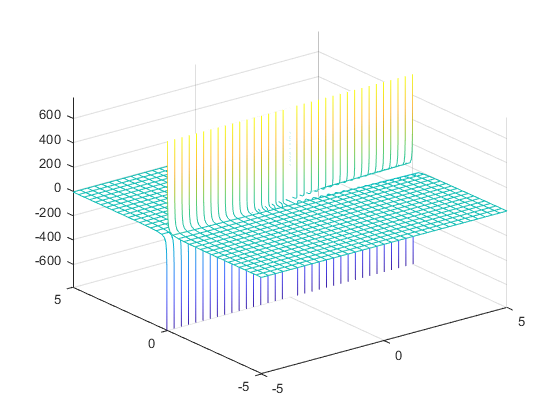

fmesh(U)